# Transformada de Fourier

**Materia**

Señales y Sistemas

**Elaborado por:**

Gael Jovani López García -** TU SKIBIDI MATRIKULA**

Diego Bejarano Bedolla - 1191498

**Maestro**

Jorgue Ibarra Esquer

## Introducción

La transformada Discreta de Fourier es una herramienta matemática utilizada para descomponer una señal en sus componentes de frecuencia. Es especialmente útil para analizar señaes periódicas o no periódicas en el dominio de la frecuencia, permitiendo estudiar la magnitud y la fase de sus componentes espectrales

Matemáticamente, la Transformada Discreta de Fourier de una señal x[n] co N muestras se representa con:

$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack *e^{-j*\frac{2*\pi }{N}*k*n}$, $k=0,1,\ldotp \ldotp \ldotp N-1$

Donde:


$$\begin{array}{l}
x\left\lbrack n\right\rbrack :\textrm{Señal}\;\textrm{en}\;\textrm{el}\;\textrm{dominio}\;\textrm{del}\;\textrm{tiempo}\\
X\left\lbrack k\right\rbrack :\textrm{Espectro}\;\textrm{de}\;\textrm{frecuencias}\\
N:\textrm{Número}\;\textrm{de}\;\textrm{muestras}
\end{array}$$


Además la operación inversa, reconstruye la señal original:


$$x\left\lbrack n\right\rbrack =\frac{1}{N}*\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack *e^{j*\frac{2\pi }{N}*k*n}$$


## Aplicaciones de la transformada Discreta de Fourier

- Procesamiento de imagenes

- Procesamiento de vídeos, sonidos

- Detección de ruido(detonaciones alrededor del mundo)

- Análisis de sistemas eléctricos

## Algoritmo de transformada rápida de Fourier(pequeño contexto)

La transformada rápida de Fourier por sus siglas FFT en inglés es la respuesta a la problematica a la transformada de Fourier, que indispensablemente era fundamental en el procesamiento de señales pero sus cálculos eran lentos ya que normalmente una sñeal de N puntos requería realizar N^2 operaciones, esto significaba que a medida que el tamañp de la señal aumentaba, el tiempo de cálculo crece de forma cuadrática

**Revolución de la transformada rápida de Fourier**

Gracias a James Cooley y John Tukey, fue desarrollado esta optimización del cálculo de DFT mediante el enfoque de "divide y vencerás", lo que redujo significativamente la complejidad computacional.

La complejidad reducida pasó de $O\left(N^2 \right)\;$a $O\left(N*\log *N\right)$

**Comparación de eficiencia**

**Proposito de este reporte**

El proposito de este reporte es aplicar de la transformada rapida de fourier para aplicar un filtro a una imagén y ver impacto claro de este concepto a una aplicación. Además, antes de aplicar FFT se mostrarán algunos ejemplos a continuación:

## Transformada Rápida de Fourier (FFT)

La "Transformación rápida de Fourier", FFT para abreviar, es un importante método de medición en la tecnología de medición de audio y acústica. Descompone una señal en sus componentes espectrales individuales y así proporciona información sobre su composición. Los FFT se utilizan para el análisis de errores, el control de calidad y la monitorización de las condiciones de las máquinas o sistemas.

**referencia(https://www.nti-audio.com/es/servicio/conocimientos/transformacion-rapida-de-fourier-fft)**


$$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack *e^{-j\frac{2\pi }{N}\mathrm{kn}}$$


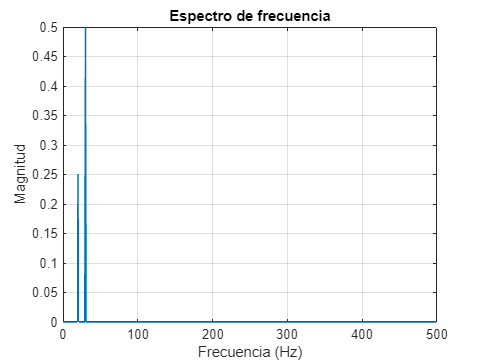

% Ejemplo FFT
fs = 1000;
t = 0:1/fs:1-1/fs;     % Vector de tiempo
f1 = 30; 
f2 = 20; 
amplitud1 = 1;       
amplitud2 = 0.5;       

% Crear la señal
senal = amplitud1 * sin(2 * pi * f1 * t) + amplitud2 * sin(2 * pi * f2 * t);

% Calcular la FFT de la señal
fft_resultado = fft(senal);
n = length(senal);    
frecuencias = (0:n-1)*(fs/n); 

% Tomar solo la mitad del espectro (frecuencias positivas)
magnitude = abs(fft_resultado/n);  % Normalizar el espectro
magnitude = magnitude(1:floor(n/2));
frecuencias = frecuencias(1:floor(n/2));

figure(1);
plot(t, senal);
title('Señal en el dominio del tiempo');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

figure(2);
plot(frecuencias, magnitude);
title('Espectro de frecuencia');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
grid on;

## **Funcion fftshift**

La función fftshift es una herramienta que se usa en combinación con la Transformada Rápida de Fourier para centrar el espectro de frecuencia alrededor de cero. Esta funcion cambia el orden de los elementos de la FFT de tal forma que las frecuencias negativas se coloquen en el centro del espectro y las frecuencias positivas se ubiquen a los lados. Esto hace que el espectro sea más fácil de interpretar, especialmente cuando se está analizando una señal en el dominio de la frecuencia.

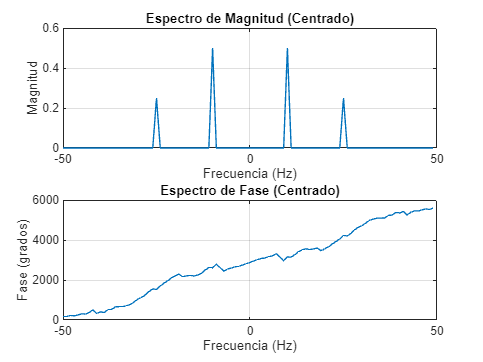

% Ejemplo FFT 
fs = 100;                         
t = 0:1/fs:1-1/fs;                 
x = sin(2*pi*10*t) + 0.5*sin(2*pi*25*t);
X = fft(x);                        
n = length(X);                     
f_shifted = (-n/2:n/2-1)*(fs/n);   

X_shifted = fftshift(X);           
magnitude_shifted = abs(X_shifted)/n; 
phase_shifted = unwrap(angle(X_shifted));

figure(1);
subplot(2,1,1);
plot(f_shifted, magnitude_shifted);
title('Espectro de Magnitud (Centrado)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
grid on;

subplot(2,1,2);
plot(f_shifted, phase_shifted*180/pi);
title('Espectro de Fase (Centrado)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');
grid on;

## **Transformada Rápida Inversa de Fourier (IFFT)**

La **Transformada Rápida Inversa de Fourier **(**IFFT**) es el proceso matemático que convierte una señal del dominio de **la **frecuencia de vuelta al dominio del tiempo. En otras palabras, es la operación inversa de la FFT (Transformada Rápida de Fourier), que convierte una señal del dominio del tiempo al dominio de la frecuencia.


$$X\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{n=0}^{N-1} X\left\lbrack k\right\rbrack *e^{j\frac{2\pi }{N}\mathrm{kn}}$$


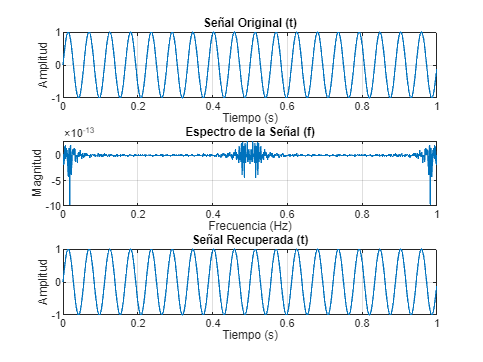

% Ejemplo IFFT
fs = 1000;              
t = 0:1/fs:1-1/fs;       

f = 18; % Frecuencia de la señal
senal_original = sin(2*pi*f*t);  

% Realizar la FFT de la señal
X = fft(senal_original);

% Aplicar la IFFT para recuperar la señal original
senal_recuperada = ifft(X);

figure;
subplot(3,1,1);
plot(t, senal_original);
title('Señal Original (t)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(3,1,2);
plot(t, real(X));  
title('Espectro de la Señal (f)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
grid on;

subplot(3,1,3);
plot(t, real(senal_recuperada));
title('Señal Recuperada (t)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

## Caso de estudio

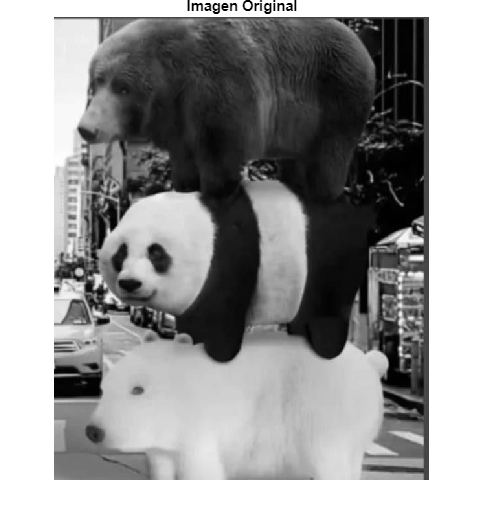

% Ejemplo imagen
img = imread('imagenSyS.jfif');
img_gray = rgb2gray(img);
imshow(img_gray);
title('Imagen Original');

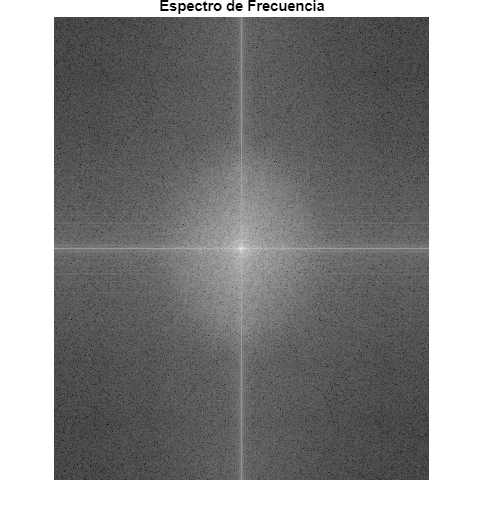


F = fft2(img_gray); % Aplicar la Transformada de Fourier bidimensional

% Desplazar el cero de la frecuencia al centro del espectro
F_shifted = fftshift(F);

% Calcular el espectro de magnitud
magnitude_spectrum = log(1 + abs(F_shifted));

% Visualizar el espectro de frecuencia
figure;
imshow(magnitude_spectrum, []);
title('Espectro de Frecuencia');